% the parameters (constants) necessary to descibe the linear state space model
%are:
%   Cyr - Cornering stiffness at rear wheel [Nrad^−1]
%   Cyf - Cornering stiffness at front wheel [Nrad^−1]
%   Izz - Inertia moment 120 [Kgm^2]
%   m - Mass [Kg]
%   Lf - Front wheelbase [m]
%   Lr - Rear wheelbase [m]
%   Gr - gear ratio [-]
%   tr - half the track of the car [m]
%   Rw - Radius of the wheel [m]
%   Vxo - Longitudinal Velocity [ms^-1] ** 
%   (**assumed constant throughout trajectory but this can vary (eg: 0-40),
%      Need to use some kind of lookup table for the PID controller gains
%      for varied ranges of long. velocity)
%   
%   (see Dissertacao.pdf p24 onwards for more info)

% (Inputs):
%   δ - Steering angle δ [rad]
%   ∆T - torque difference at the rear wheels [Nm]
%
% Xdot = [Vy_dot
%         Yaw_doubledot]

% X = [Vy
%      Yaw_dot]
%
% U = [∆T
%      δ]

Cyr = 21429

Cyr = 21429

Cyf = 15714

Cyf = 15714

Izz = 120

Izz = 120

m = 356

m = 356

Lf = 0.873

Lf = 0.8730

Lr = 0.717

Lr = 0.7170

Gr = 4.4

Gr = 4.4000

tr = 0.65

tr = 0.6500

Rw = 0.265

Rw = 0.2650

Vxo = 13

Vxo = 13


% for calculating ∆T from Mz (assisting yaw moment)
k = Rw/(2*tr*Gr)

k = 0.0463


%sanity
A11 = -(Cyf+Cyr)/(m*Vxo)

A11 = -8.0257

A12 = (Lr*Cyr-Lf*Cyf)/(m*Vxo)-Vxo

A12 = -12.6443

A21 = (Lr*Cyr-Lf*Cyf)/(Izz*Vxo)

A21 = 1.0553

A22 = -(Lf^2*Cyf+Lr^2*Cyr)/(Izz*Vxo)

A22 = -14.7388


B11 = 0

B11 = 0

B12 = Cyf/(m*Vxo)

B12 = 3.3954

B21 = 1/(Izz)

B21 = 0.0083

B22 = (Lf*Cyf)/Izz

B22 = 114.3194


% 'A' matrix calculations
A = [A11 A12;
     A21 A22]

A =    -8.0257  -12.6443
    1.0553  -14.7388


%A = [A21 A22]

% 'B' matrix calculations 
B = [B11 B12;
     B21 B22]

B =          0    3.3954
    0.0083  114.3194


%B = [B21 B22]
%B = [0 0;
%     B21 B22]

% 'C' = I
C = eye(2)

C =      1     0
     0     1


%C = [1 1]

% No 'D' feedforward matrix (yet?)
D = 0

D = 0


states = {'Lateral Velocity','Yaw Rate'};
inputs = {'Yaw Moment','Steer Angle'};
%states = {'yaw rate', 'lateral velocity'};
%inputs = {'steer angle', 'delta T'};
outputs = states;

bike_model = ss(A,B,C,D,'statename', states, 'inputname', inputs, 'outputname', outputs)


bike_model =
 
  A = 
                 Lateral Velo
   Lateral Velo        -8.026
   Yaw Rate             1.055
 
                     Yaw Rate
   Lateral Velo        -12.64
   Yaw Rate            -14.74
 
  B = 
                  Yaw Moment
   Lateral Velo            0
   Yaw Rate         0.008333
 
                 Steer Angle
   Lateral Velo        3.395
   Yaw Rate            114.3
 
  C = 
                 Lateral Velo
   Lateral Velo             1
   Yaw Rate                 0
 
                     Yaw Rate
   Lateral Velo             0
   Yaw Rate                 1
 
  D = 
                  Yaw Moment
   Lateral Velo            0
   Yaw Rate                0
 
                 Steer Angle
   Lateral Velo            0
   Yaw Rate                0
 
Continuous-time state-space model.



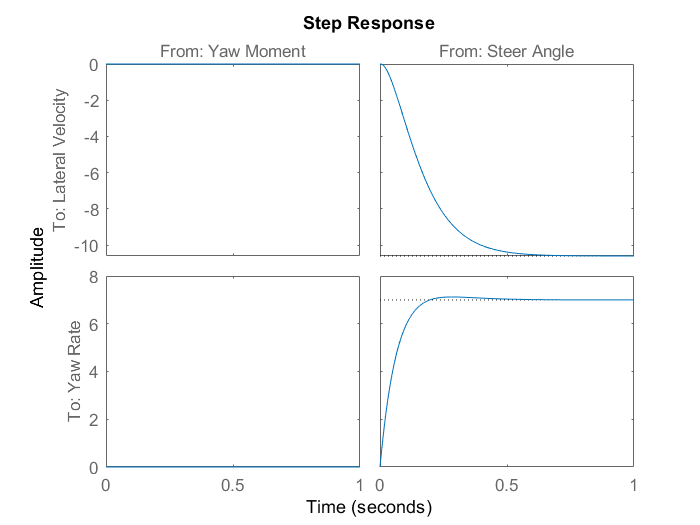


%tf(bike_model)
%isstable(bike_model)
step(bike_model)

%controllability_matrix = ctrb(bike_model)
%rank(controllability_matrix)